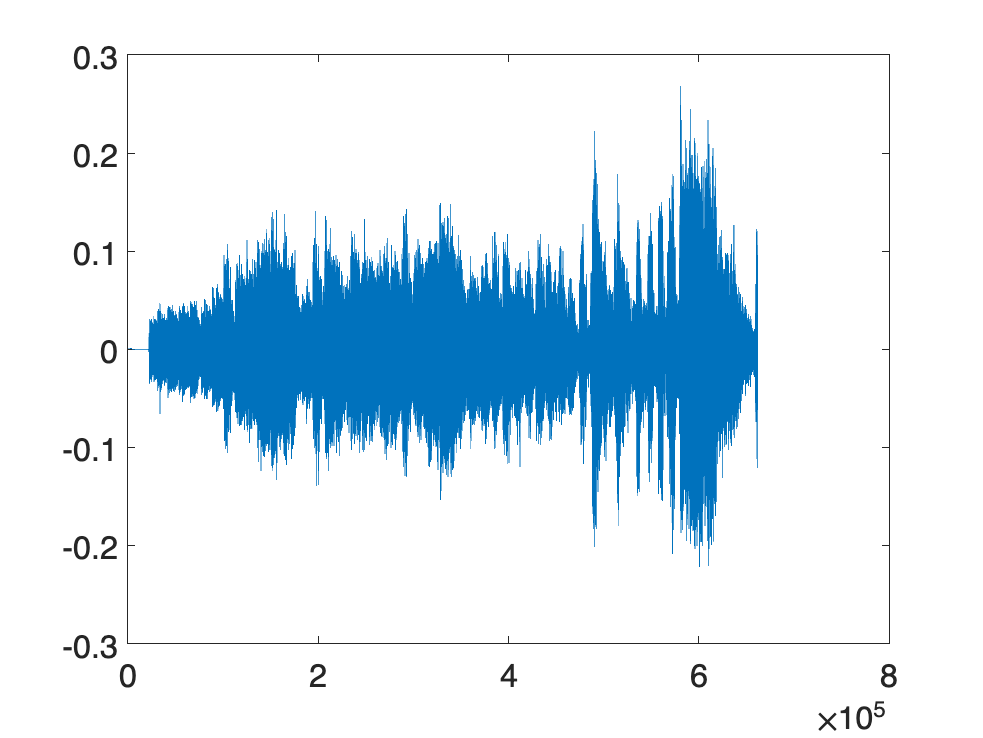

%The following reads the data file, and plots the file
[y,Fs] = audioread('PinkPanther30.wav');

%Because the sound signals have 2 channels, we will just analyze the first channel
y = y(:,1);

figure(1)
plot(y)
set(gca,'fontsize',18)

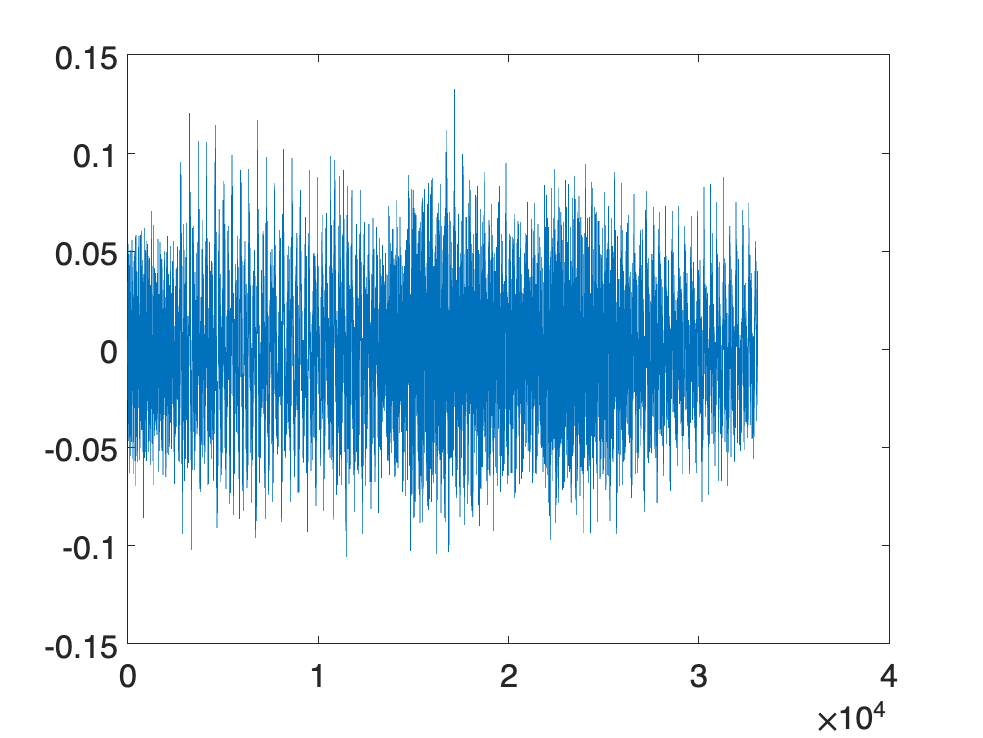


% Find the length of y
L = length(y);


% Determine starting and ending points of your clipping by looking at plot 1
% Note these must be integers that are not 0!
index1 = round(L*0.35); % CHANGE THIS NUMBER
index2 = round(L*0.4); % CHANGE THIS NUMBER

sound(y(index1:index2),Fs)  % Play the file
newsignal = y(index1:index2);  % Clips sound signal to new signal that starts at index1 and goes to index2
figure(2)
plot(newsignal)
set(gca,'fontsize',18)